 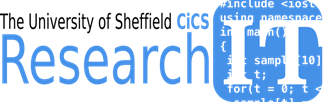

# **Exercises for Data Visualisation with Matlab**

**Obtaining the Examples**

- The course examples are available under the CIC6007 course on the online learning system, see matlab examples under the course content

The matlab examples zip file can also be downloaded from

     [http://rcg.group.shef.ac.uk/courses/cic6007 /matlab_examples.zip](http://rcg.group.shef.ac.uk/courses/cic6007 /matlab_examples.zip)

Iceberg users may extract the examples from a tgz archive in the directory  /usr/local/courses on iceberg.

On ShARC, use cd to change directory to a working directory of your choice then use the cp and tar commands to obtain and extract the examples.

The required commands are

 cd ~/myworkingdirectory

 tar –zxvf /usr/local/courses/matlab_examples.tgz

# Practice Session 1

## Exercises  : Importing Data and Plotting in MATLAB

In the exercise directory you will find a data file named *field.dat* .    

1  Read it into MATLAB and store columns 1 to 3 of the data as; temperature, pressure and density respectively

%Use Import Data from the home bar  or  Start -> Import Wizard .  This should read all the data into a variable called FIELD. Then;   temp = FIELD(:,1) ; 
%pres = FIELD(:,2) ;  dens = FIELD(:,3);
field=readtable('field.dat');
[frows,fcols]=size(field)
temp=field.Var1
pres=field.Var2
dens=field.Var3


2  Using the PLOT command plot temperature variation

3  Using the PLOT command plot pressure variation

4  By making use of the HOLD command, plot both temperature and pressure in the same graph.

plot(temp) ;
plot(pres) ;
hold on ; plot(temp , 'g' ) ;



5   Fit a 5th degree polynomial to the data, display the equation on the graph and save the fitting parameters into the workspace via the Tools > Basic Fitting menu of the Figure window

%for help use 
%e.g. use [p,S] = polyfit(x,y,n)
help polyfit
[p,S] = polyfit(1:frows,temp,5)

6 Compute the max, min, mean and median values of the plot variables

7  Plot the mean value of y as a line on the current plot ( Hint: contract two end points of a line using values from the basic statistics and use them in a call to line command  but don’t forget to use the hold command first)

8  Using the edit-plot icon from the figure window toolbar edit this graph to change the colour of the mean-value line and the legend for it.

% eg. use
field=temp;
y = [mean(field),median(field),max(xfield),min(field)]

9  Using the SUBPLOT command. Plot three separate plots of all three variables on the same screen. Experiment with editing other aspects of the plot.

subplot(2,2,1); plot(temp)
subplot(2,2,2); plot(dens)
subplot(2,2,3); plot(pres)

## Exercise 2: Basic graphics

TASK 1 - edit trend.txt in the data folder  ( by double clicking on it in matlab folder to view ) to see what it contains.

 It is possible to read well constracted data files such as trend.txt  into matlab by using the` load` command.

 type:  DOC LOAD   and investigate help on using the LOAD command.

 Read in this trend.txt into MATLAB using the LOAD command.

Y=load('..\data\trend.txt')

Y =   264.7920  300.7650
  276.0750  304.8550
  256.7200  290.1760
  272.8350  282.6810
  290.9010  271.0990
  308.8470  263.7020
  333.2470  248.6270
  322.3900  264.0210
  353.2540  210.7080
  349.7380  190.8140


TASK 2

Save each column as a seperate variable by using vector assignments calling them y1  and y2 

Plot Y1  using the PLOT command.

  
  plot (Y) ;
  y1=Y(:,1);
  y2=Y(:,2);





Constract a vector called x  that is the same length and shape as y1 

and contains numbers from 1 to 100 ( or scaled by 100 so that it runs from 0.01 to 1.00

 HINT you can either use notation the : notation. I.e start:interval:stop or  LINSPACE function .

 Plot y1 against x 

HINT: type `help plot`  to find out about the use of plot command. 

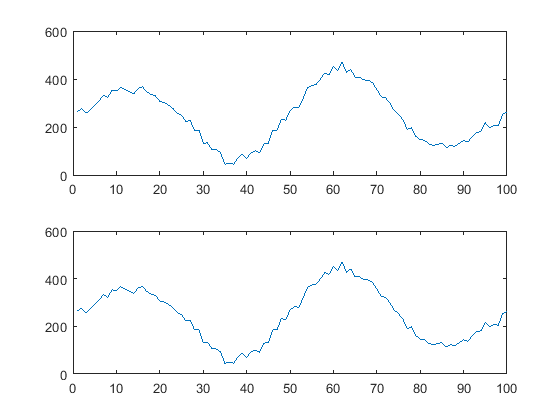

  x=1:100;
  plot(x,y1);

TASK 3: Plotting multiple curves in one graph. 

Open another graphics window. HINT: use FIGURE command.

 Plot y1 against x and y2 against x on the same plot using a single PLOT  command. 

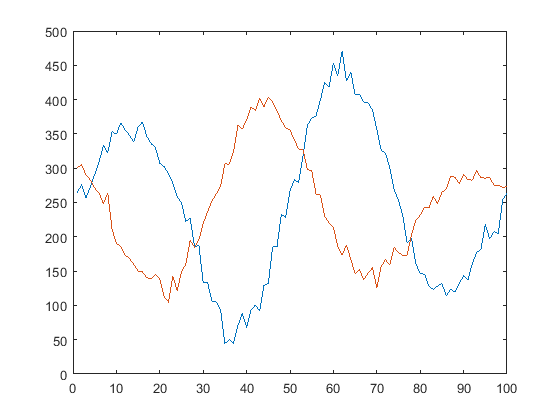

figure;
plot(x,y1,x,y2);

TASK 4: Overlaying Plots

Plot y1 against x and y2 against x on the same plot   but this time use two PLOT commands.

 HINT: use hold command.

figure
plot(x,y1);
hold on
plot(x,y2);
hold off;

TASK 5 :  Using subplots 

Split your graphics window into two sections and plot y1 in one section and scattered values of y1 in another section.

HINT: Use SUBPLOT and SCATTER commands. 

subplot(2,1,1)
plot(x,y1)
subplot(2,1,2)
scatter(x,y1)


TASK 6 : Properties of Graphical objects

 Draw a scatter plot of y1 

 Fill the data markers with red colour.

 HINT: Save the handle of the scatter plot while creating it.

 Redefine the MarkerFaceCOlor property of the plot to be red ( i.e. 'r' ) 

 HINT : assign a value to  object.PropertyName

subplot(1,1,1);
s1=scatter(x,y1,[],'rs','filled','MarkerFaceAlpha',0.2)


TASK 6 : Decorating a graph

 Use the commands  TITLE , XLABEL , YLABEL  to label the graph.

title('trends')
xlabel('time')
ylabel('trend value')

 Inspect the values for axes properties

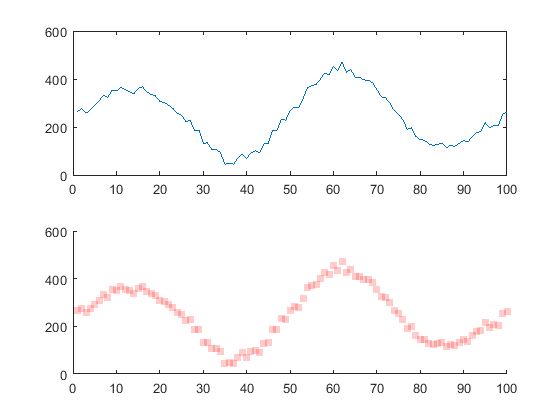

                       ALim: [0 1]
                   ALimMode: 'auto'
     ActivePositionProperty: 'position'
          AmbientLightColor: [1 1 1]
               BeingDeleted: 'off'
                        Box: 'off'
                   BoxStyle: 'back'
                 BusyAction: 'queue'
              ButtonDownFcn: ''
                       CLim: [0 1]
                   CLimMode: 'auto'
             CameraPosition: [50 300 17.3205]
         CameraPositionMode: 'auto'
               CameraTarget: [50 300 0]
           CameraTargetMode: 'auto'
             CameraUpVector: [0 1 0]
         CameraUpVectorMode: 'auto'
            CameraViewAngle: 6.6086
        CameraViewAngleMode: 'auto'
                   Children: [1×1 Scatter]
                   Clipping: 'on'
              ClippingStyle: '3dbox'
                      Color: [1 1 1]
                 ColorOrder: [7×3 double]
            ColorOrderIndex: 2
                  CreateFcn: ''
               CurrentPoint: [2×3 double]
     

ax=get(gca ) 

% Use the set command to change the range of the y axis limits by filling
% in the missing two parameters of the following set command;
% set ( gca , '......' , '.......' ) 






# Practice Session 2

## Exercise 3

Create a filled scatter plot that plots the `data.Windspeed`values at sea, i.e., values not on land (`~onland`), along the x-axis and the corresponding `data.Pressure` values along the y-axis. Use circular markers with blue color. Make sure the marker faces are semitransparent and have blue color.

% create a new variable named data.HurrCat that contains the 
% hurricane category of the observation based on data.Windspeed.
data = readtable('..\data\hurricaneData1990s-v2.txt','HeaderLines',5);

%if any windspeeds are NaN set to zero
idwindnan = find(isnan(data.Windspeed));
data.Windspeed(idwindnan)=0;

sz=size(data);
a=data.Country;
for i=1:sz(1)
  if isequal(a{i},'N/A' )
      data.Location{i} = 'Sea';
      onland(i)=0;
  else
      data.Location{i} = 'Land';
      onland(i)=1;
  end
end

data.Location;

figure
hold on
%TODO Create a filled scatter plot that plots the data.Windspeedvalues at sea, i.e., values not on land (~onland), 
% along the x-axis and the corresponding data.Pressure values along the y-axis. Use circular markers with blue color. 
scatter(data.Windspeed(~onland),data.Pressure(~onland),'b','filled','MarkerFaceAlpha',0.5)
scatter(data.Windspeed(onland==1),data.Pressure(onland==1),'r','filled','MarkerFaceAlpha',0.5)
hold off

Change the x-axis limits to go from 15 to 60 and add minor grid lines to the scatter plot.

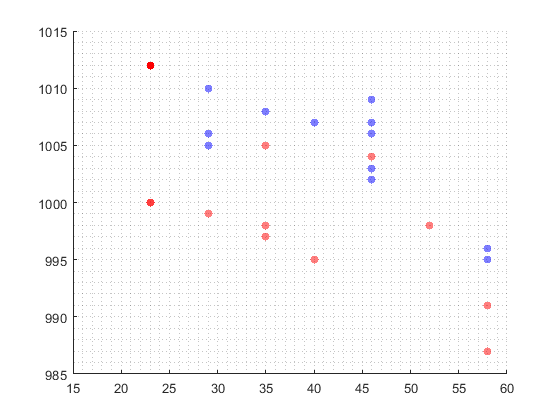

%TODO change limit and grid
xlim([15 60])
grid('minor') %add minor states

Plotting bargraphs and binning data and using discretization



% Find index of on-land and on-sea observation index
SSscale = [0 39 74 96 111 130 157 Inf];
catnames = {'TD','TS','1','2','3','4','5'};
data.HurrCat = discretize(data.Windspeed,SSscale,'Categorical',catnames)

data = 51×7 table
    Number         Timestamp              Country        Windspeed    Pressure    Location    HurrCat
    ______    ____________________    _______________    _________    ________    ________    _______

    1         29-Jun-1991 12:00:00    'N/A'               23          1012        'Sea'       TD     
    1         29-Jun-1991 18:00:00    'N/A'               23          1012        'Sea'       TD     
    1         30-Jun-1991 00:00:00    'N/A'                0          1012        'Sea'       TD     
    1         30-Jun-1991 06:00:00    'United States'     23          1012        'Land'      TD     
    1         30-Jun-1991 12:00:00    'United States'     23          1012        'Land'      TD     
    1         30-Jun-1991 18:

windBinNo = discretize(data.Windspeed,SSscale);

sz=size(SSscale)

sz =      1     8


szw=size(windBinNo)

szw =     51     1


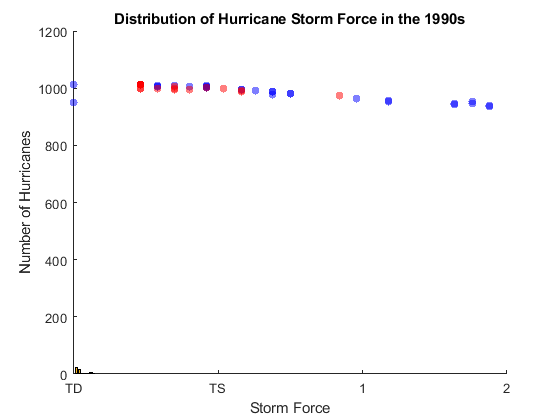

numwindbin=zeros(sz(2)-1,1);
for i=1:szw(1)
    windbin=windBinNo(i);
    numwindbin(windbin)=numwindbin(windbin)+1;
end

%%TODO plot the barchart of the number in each bin
bar(numwindbin);
title('Distribution of Hurricane Storm Force in the 1990s');
xlabel('Storm Force');
ylabel('Number of Hurricanes');
set(gca,'XTickLabel',catnames);

Exercise to Load data and 

The file 'fuelEconomy.txt' contains fuel economy data for different models of cars (you can use the command `edit` `fuelEconomy.txt` to examine its contents). 

The goal of this exercise is to divide the combined miles per gallon data into three classes and create a scatter plot of city and highway miles per gallon like the one shown below.

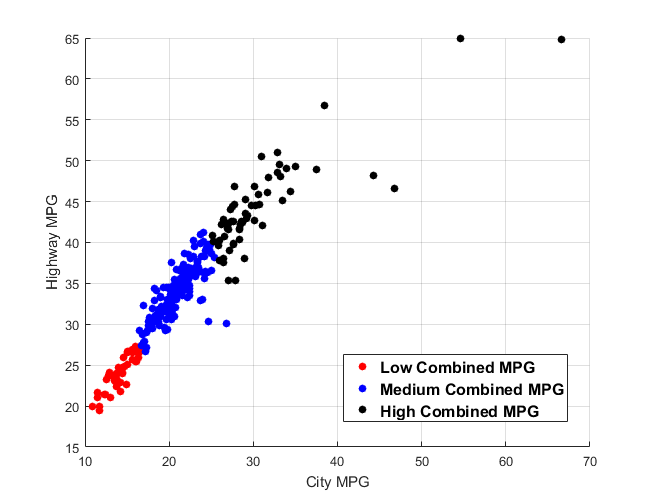

Follow the steps listed below:

Step 1 – Import the data into a table.

Step 2 – The variable `CombinedMPG` contains missing values represented by NaN. Remove the rows corresponding to these missing values from the imported table.

Step 3 – Discretize the `CombinedMPG` variable into three classes called 'Low', 'Medium', and 'High' using the bin edges 0, 20, 30, and 70 (values greater than or equal to 0 and less than 20 are classified as 'Low' and so on). Store the discretized result in a variable named `MPGClass`.

Step 4 – Create a scatter plot with `CityMPG` on the x-axis and `HighwayMPG` on the y-axis. Observations with 'Low' combined MPG should be colored red (`'r'`), 'Medium' should be blue (`'b'`), and 'High' should be 'black' (`'k'`).

%TODO step 1
% Read data
data=readtable('../data/fuelEconomy.txt')

data = 386×7 table
        Class             Make                    Model              NumCyl    CityMPG    HighwayMPG    CombinedMPG
    _____________    _______________    _________________________    ______    _______    __________    ___________

    'TWO SEATERS'    'ASTON MARTIN'     'DBS COUPE'                  12          14.4       24.7        17.726     
    'TWO SEATERS'    'ASTON MARTIN'     'V8 VANTAGE'                  8        15.938     26.855        19.506     
    'TWO SEATERS'    'AUDI'             'R8'                          8            11     25.045        18.628     
    'TWO SEATERS'    'AUDI'             'TT ROADSTER'                 4          28.5       42.2        33.376     
    'TWO SEATERS'    'AUDI'             'TT RO

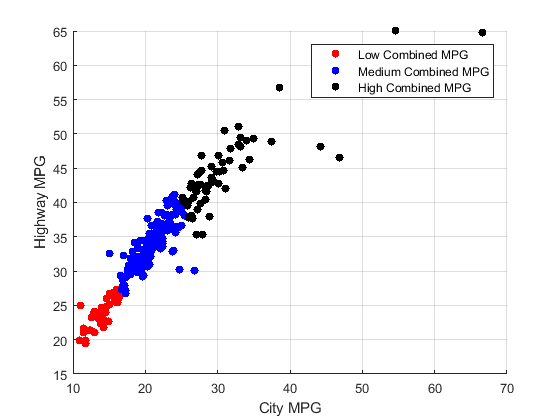

%TODO step 2
% Identify the rows containing NaN values and remove them
nanIdx = ismissing(data.CombinedMPG);
data(nanIdx,:) = [];

%TODO step 3 hint use the discretize function
% Discretize Combined MPG
MPGClass = discretize(data.CombinedMPG,[0 20 30 70],{'Low' 'Medium' 'High'});

% Optional - Convert the class into a categorical array
MPGClass = categorical(MPGClass);

%TODO step 4
% Extract observations for various classes and plot them
scatter(data.CityMPG(MPGClass == 'Low'),data.HighwayMPG(MPGClass == 'Low'),...
'r','filled')
hold on
scatter(data.CityMPG(MPGClass == 'Medium'),data.HighwayMPG(MPGClass == 'Medium'),...
'b','filled')
hold on
scatter(data.CityMPG(MPGClass == 'High'),data.HighwayMPG(MPGClass == 'High'),...
'k','filled')
hold off

grid on
xlabel('City MPG')
ylabel('Highway MPG')
legend('Low Combined MPG','Medium Combined MPG','High Combined MPG');

## Exercise 4: Interpolating Scattered Data

Modify the script for the Australian surface temperature data so that it interpolates the raw data given by `lon`, `lat` and `T` and evaluates the data at the points in the XY grid where the x-data goes from 110 to 155 and the y-data goes from -45 to -10, both in unit steps. The interpolated values should be stored in an array named `Tgrid`.

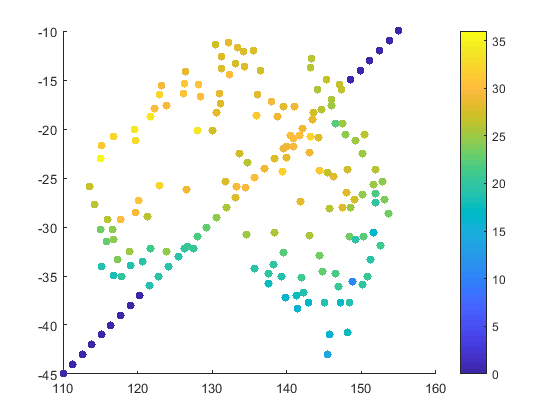

%% Import data
clf
data=readtable('../data/australia_march_temps.csv');

%% Extract data
lon = (data.longitude)';
lat = (data.latitude)';
T = (data.temperature)';

scatter(lon,lat,[],T,'filled')
colorbar
hold on

%TODO
% Create vectors for new longitude and latitude values
lonvec = linspace(110,155,36);
latvec = linspace(-45,-10,36);

%TODO interpolate temperature data T using griddata function
Tnew = griddata(lon,lat,T,lonvec,latvec);
% Create a grid of longitudes and latitudes
[longrid,latgrid] = meshgrid(lonvec,latvec);

% Interpolate the scattered March temperature data onto the grid
%Tgrid = griddata(lonvec,latvec,T,longrid,latgrid);

id=(isnan(Tnew));
idn=find(id);
Tnew(idn)=0;

scatter(lonvec,latvec,[],Tnew,'filled')

## Exercise: Visualising Surfaces

Use `meshgrid` to create a grid of x-, y-data using the `x`- and `y`-arrays. Store the grid arrays as `X` and `Y`.

%TODO use meshgrid
[X,Y]=meshgrid(x,y);

Create an array named `Z` which contains the calculation below for each *x*-*y* point in the XY grid.

`sin``(``x``)` `+` `cos``(``y``)`

%TODO define Z here
Z=sin(X)+cos(Y);

**Info:** You can use the `surf` function to create a surface plot.

`>> ``[``X``,``Y``]` `=` `meshgrid``(``0``:``0.1``:``1``,``-2``:``0.2``:``2``)``;`

`>> ``Z` `=` `X``*``Y`

`>> ``surf``(``X``,``Y``,``Z``)`

Create a surface plot of the Z data over the entire XY grid.

%TODO
surf(X,Y,Z)

Study how the following surface changes

X = [ 0  0  0.25
      1  1  0.75 ];
Y = [ 20  21  21
      20  21  21 ];
Z = [ 105  105  105.5
      105  105  105.5 ];

surf(X,Y,Z)

Now try the following surface, observe how this changes and how the surface points are linked

X = [ 0  0  0.25  0
      1  1  0.75  1 ];
Y = [ 20  21  21  21
      20  21  21  21 ];
Z = [ 105  105  105.5  106
      105  105  105.5  106 ];
surf(X,Y,Z)

In the surface below swap 0.25 and 0.75 for the X coordinate and observe hpw the plat changes


X = [ 0     1 
      0.25  0.75 ];
Y = [ 0 0
      1 1 ];
Z = [ 1 1
      1 1 ];

surf(X,Y,Z)

Create a surface plot of the data in the file data/natick.txt. Make the lines between the patches invisible, and interpolate the face colors of the patches.

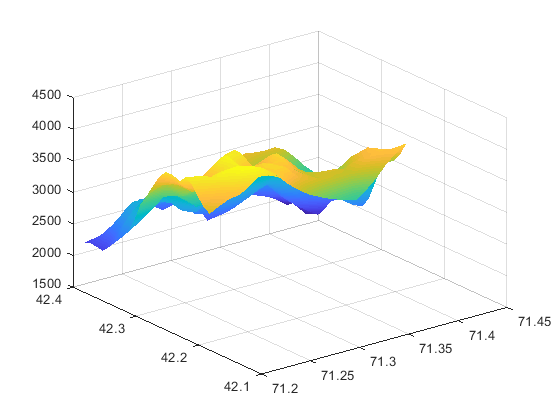

%% Import data
fid = fopen('../data/natick.txt');
data = textscan(fid,'%f%f%f','HeaderLines',1);
fclose(fid);

%% Extract data
x = data{1};
y = data{2};
z = data{3};

%% Create an XY grid from the raw data
xv = min(x):0.01:max(x);
yv = min(y):0.01:max(y);
[X,Y] = meshgrid(xv,yv);

%% Interpolate the raw data and evaluate it on the X,Y grid
Z = griddata(x,y,z,X,Y);

%%TODO modify the properties for the surface hint EdgeColor and FaceColor
%% Create a surface plot of the data
s = surf(X,Y,Z);
s.EdgeColor = 'none';
s.FaceColor = 'interp';

In the casestudies/membrane folder study the script membrane. Modify the surf plot so that the face have transparency, interpolation is used to shade the faces

 and so that there are no  lines between them. Run the script from the matlab workbench.

The surface plot created by the script displays elevation data.

Modify the script so that:

- The `autumn` colormap is used

- A colorbar is added to the figure

- The colormap values are in the range 3000 to 4000

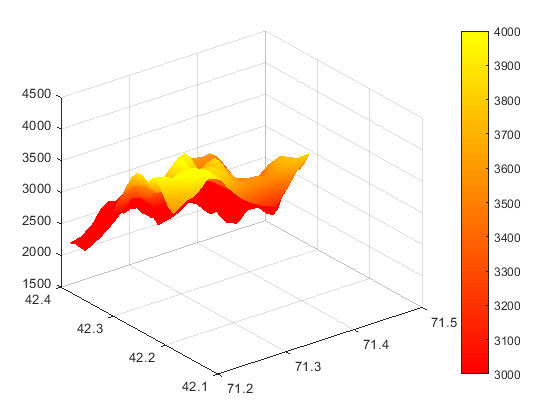

%% Import data
fid = fopen('../data/natick.txt');
data = textscan(fid,'%f%f%f','HeaderLines',1);
fclose(fid);

%% Extract data
x = data{1};
y = data{2};
z = data{3};

%% Create an XY grid from the raw data
xv = min(x):0.01:max(x);
yv = min(y):0.01:max(y);
[X,Y] = meshgrid(xv,yv);

%% Interpolate the raw data and evaluate it on the X,Y grid
Z = griddata(x,y,z,X,Y);

%%TODO
%% Create a surface plot of the data
s = surf(X,Y,Z);
s.EdgeColor = 'none';
s.FaceColor = 'interp';

colormap('autumn');
colorbar;

ax=gca;
ax.CLim=[3000 4000]; %change the c limits

Modify the script for the Australian temperatures data so that it creates a pseudocolor image of `Tgrid` as a function of longitude and latitude.

Customize the appearance of the surface so that the lines between the patches have some transparency.

Create another figure that contains the scaled image of the same data. Make sure that the *y* coordinates are numbered from bottom-to-top. Also, make sure that the correct *x*- and *y*-data is plotted.

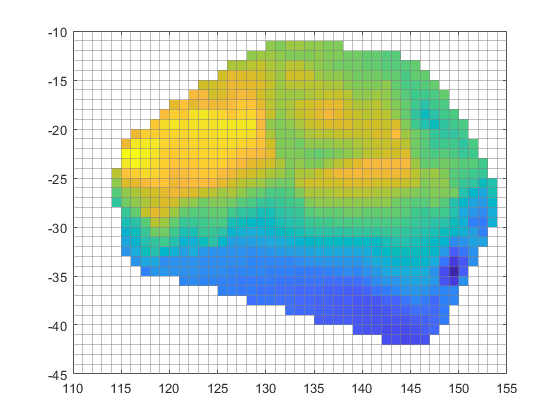

%% Import data
clf
data=readtable('../data/australia_march_temps.csv');

%% Extract data
lon = (data.longitude)';
lat = (data.latitude)';
T = (data.temperature)';

% Create vectors for new longitude and latitude values
lonvec = 110:155;
latvec = -45:-10;

% Create a grid of longitudes and latitudes
[longrid,latgrid] = meshgrid(lonvec,latvec);

% Interpolate the scattered March temperature data onto the grid
Tgrid = griddata(lon,lat,T,longrid,latgrid);

%% TODO: Create two images of the temperature data
figure
im = pcolor(longrid,latgrid,Tgrid);

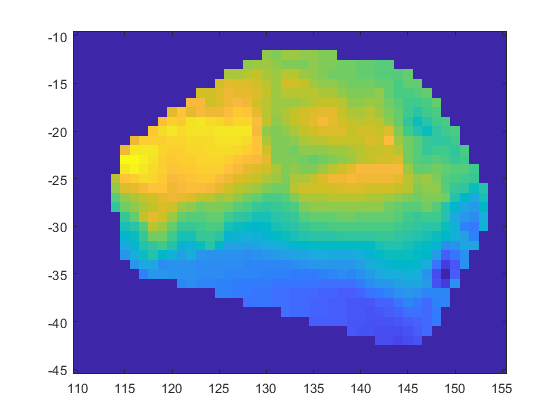

im.EdgeColor = 0.5*[1 1 1];
im.EdgeAlpha = 0.5;

figure

im2 = imagesc(lonvec,latvec,Tgrid);
axis xy

